Values for the plane/line

n = [0 1 0.5]; % Plane normal
p = [0 0 1]; % Plane point

q = [-1 -1 0]; % Line point 1
r = [1 1 0]; % Line point 2


Plot a plane and the intersection

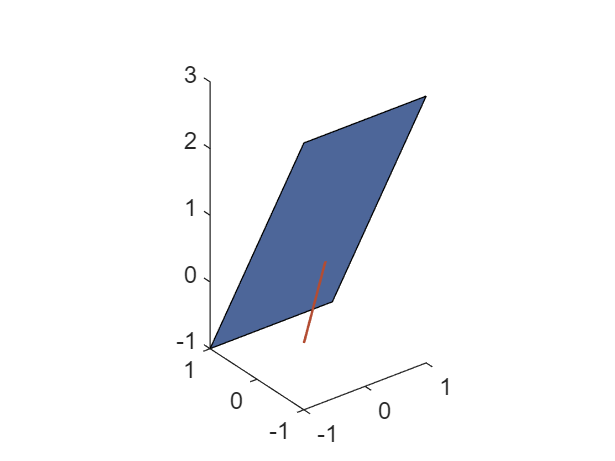

% Create the plot
cla
plot3([q(1),r(1)],[q(2),r(2)],[q(3),r(3)],...
    'color',[0.7,0.3,0.2],'LineWidth',1)
hold on
x = linspace(-1,1,2);
[X,Y] = meshgrid(x,x);
Z = -( n(1)*(X-p(1)) + n(2)*(Y-p(2)) )/n(3) + p(3);
surf(X,Y,Z,'FaceColor',[0.3, 0.4, 0.6])
hold off
axis equal

v = r-q;
if( v(3)~=0 && any([n(3),v(1),v(2)]~=0) )
    Al = [ v(3)     0 -v(1);
              0  v(3) -v(2)];
    bl = [-v(3)*q(1) + v(1)*q(3);
          -v(3)*q(2) + v(2)*q(3)]
elseif( v(1)~=0 && any([n(1),v(2),v(3)]~=0) )
    Al = [ v(2) -v(1)     0;
           v(3)    0  -v(1)];
    bl = [-q(1)*v(2) + v(1)*q(2);
          -q(1)*v(3) + v(1)*q(3)];
else
    Al = [ v(2) -v(1)    0;
           v(3)    0  -v(2)];
    bl = [-q(1)*v(2) + v(1)*q(2);
          -q(2)*v(3) + v(2)*q(3)];
end

A = [Al; n];
b = [bl; dot(n,-p)];

if(abs(det(A))<1e-12)
    s = [NaN, NaN, NaN];
else
    s = (A\-b)';
end

s

s =     0.5000    0.5000         0


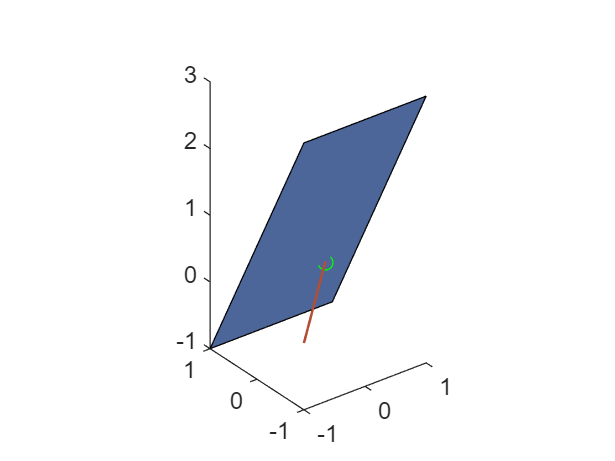


hold on
plot3(s(1),s(2),s(3),'go')
hold off